clear
load('./traces_v5/input_sets_second_op_31.mat');
numberOfSets = 1000;
setSize = 31;

%Get the mean traces by sets of 31
meanTraces = getMeanTraces(traces_Y,numberOfSets,setSize)

meanTraces =    -0.0001   -0.0001   -0.0002   -0.0003   -0.0003   -0.0004   -0.0004   -0.0004   -0.0003   -0.0003   -0.0004   -0.0005   -0.0005   -0.0005   -0.0005   -0.0006   -0.0007   -0.0008   -0.0008   -0.0008   -0.0007   -0.0006   -0.0005   -0.0004   -0.0005   -0.0005   -0.0006   -0.0006   -0.0005   -0.0005   -0.0003   -0.0001    0.0000    0.0002    0.0003    0.0005    0.0006    0.0007    0.0009    0.0012    0.0014    0.0017    0.0019    0.0020    0.0021    0.0021    0.0021    0.0021    0.0020    0.0020
   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0003   -0.0004   -0.0005   -0.0006   -0.0005   -0.0004   -0.0003   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0001   -0.0001   -0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0003    0.0004    0.0005    0.0007    0.0008    0.0010    0.0012    0.0014    0.0016    0.0018    0.0020    0.0022    0.0024    0.0025    0.0026    0.0026    0.0025    0.

% Vectors for the ROC curve:
falsePositiveRates = zeros(1,16);
truePositiveRates = zeros(1,16);
index = 0;

## **Correlation**

threshold = 0.9964;
%Mean traces
[confusionMatrix,type1Errors, type2Errors] = getConfusionMatrixCorr(meanTraces,inputs_b(1:setSize:size(inputs_b,1),:),threshold);

%Calculate accuracy, false positives, false negatives
confusionMatrix

confusionMatrix =        52709       15403
      256894      174494


comparisons = confusionMatrix(1,1) + confusionMatrix(1,2) + confusionMatrix(2,1) + confusionMatrix(2,2);
falsePosRate = getFalsePositiveRate(confusionMatrix)

falsePosRate = 0.5955

falseNegRate = getFalseNegativeRate(confusionMatrix)

falseNegRate = 0.2261

accuracy = getAccuracy(confusionMatrix)

accuracy = 0.4549

index = index + 1;
falsePositiveRates(index) = falsePosRate;
truePositiveRates(index) = 1 - falseNegRate;

freq = 100e6;
samplesPerSec = 40e9;
samplesPerCycle = samplesPerSec/freq

samplesPerCycle = 400

compressTraceSize = ceil(size(traces_Y,2)/samplesPerCycle)

compressTraceSize = 51

% Try using the max by clock cycle after doing the average
compressTraces1 = compressMaxWithoutSync(meanTraces,compressTraceSize,samplesPerCycle);
threshold = 0.9953;

%Calculate accuracy, false positives, false negatives
confusionMatrix = getConfusionMatrixCorr(compressTraces1,inputs_b(1:setSize:size(inputs_b,1),:),threshold);
confusionMatrix

confusionMatrix =        55619       12493
      261356      170032


comparisons = confusionMatrix(1,1) + confusionMatrix(1,2) + confusionMatrix(2,1) + confusionMatrix(2,2);
falsePosRate = getFalsePositiveRate(confusionMatrix)

falsePosRate = 0.6058

falseNegRate = getFalseNegativeRate(confusionMatrix)

falseNegRate = 0.1834

accuracy = getAccuracy(confusionMatrix)

accuracy = 0.4518

index = index + 1;
falsePositiveRates(index) = falsePosRate;
truePositiveRates(index) = 1 - falseNegRate;

% Try using the average by clock cycle after doing the average
compressTraces2 = compressAvgWithoutSync(meanTraces,compressTraceSize,samplesPerCycle);
threshold = 0.9990;
%Calculate accuracy, false positives, false negatives
confusionMatrix = getConfusionMatrixCorr(compressTraces2,inputs_b(1:setSize:size(inputs_b,1),:),threshold);

confusionMatrix

confusionMatrix =        49273       18839
      293229      138159


comparisons = confusionMatrix(1,1) + confusionMatrix(1,2) + confusionMatrix(2,1) + confusionMatrix(2,2);
falsePosRate = getFalsePositiveRate(confusionMatrix)

falsePosRate = 0.6797

falseNegRate = getFalseNegativeRate(confusionMatrix)

falseNegRate = 0.2766

accuracy = getAccuracy(confusionMatrix)

accuracy = 0.3752

index = index + 1;
falsePositiveRates(index) = falsePosRate;
truePositiveRates(index) = 1 - falseNegRate;

%Max per clock in original traces
compressTraces3 = compressMaxWithoutSync(traces_Y,compressTraceSize,samplesPerCycle);
compressTraces3 = getMeanTraces(compressTraces3,numberOfSets,setSize);
threshold = 0.9968;

confusionMatrix = getConfusionMatrixCorr(compressTraces3,inputs_b(1:setSize:size(inputs_b,1),:),threshold);

confusionMatrix

confusionMatrix =        55025       13087
      259322      172066


comparisons = confusionMatrix(1,1) + confusionMatrix(1,2) + confusionMatrix(2,1) + confusionMatrix(2,2);
falsePosRate = getFalsePositiveRate(confusionMatrix)

falsePosRate = 0.6011

falseNegRate = getFalseNegativeRate(confusionMatrix)

falseNegRate = 0.1921

accuracy = getAccuracy(confusionMatrix)

accuracy = 0.4546

index = index + 1;
falsePositiveRates(index) = falsePosRate;
truePositiveRates(index) = 1 - falseNegRate;

% compressTraces4 = compressAvgWithoutSync(traces_Y,compressTraceSize,samplesPerCycle);
% compressTraces4 = getMeanTraces(compressTraces4,numberOfSets,setSize);
% threshold = 0.993485561123956;
% 
% 
% confusionMatrix = getConfusionMatrixCorr(compressTraces4,inputs_b(1:setSize:size(inputs_b,1),:),threshold);
% 
% confusionMatrix
% comparisons = confusionMatrix(1,1) + confusionMatrix(1,2) + confusionMatrix(2,1) + confusionMatrix(2,2);
% falsePosRate = getFalsePositiveRate(confusionMatrix)
% falseNegRate = getFalseNegativeRate(confusionMatrix)
% accuracy = getAccuracy(confusionMatrix)

clockIndexes = getClockIndexes();

% Try using the max by clock cycle but sync after doing the average
compressTraces5 = compressMaxWithSync(meanTraces,clockIndexes);
threshold = 0.9962;

%Calculate accuracy, false positives, false negatives
confusionMatrix = getConfusionMatrixCorr(compressTraces5,inputs_b(1:setSize:size(inputs_b,1),:),threshold);
confusionMatrix

confusionMatrix =        52158       15954
      266505      164883


comparisons = confusionMatrix(1,1) + confusionMatrix(1,2) + confusionMatrix(2,1) + confusionMatrix(2,2);
falsePosRate = getFalsePositiveRate(confusionMatrix)

falsePosRate = 0.6178

falseNegRate = getFalseNegativeRate(confusionMatrix)

falseNegRate = 0.2342

accuracy = getAccuracy(confusionMatrix)

accuracy = 0.4345

index = index + 1;
falsePositiveRates(index) = falsePosRate;
truePositiveRates(index) = 1 - falseNegRate;

% Try using the average by clock cycle after doing the average but sync'ed
compressTraces6 = compressAvgWithSync(meanTraces,clockIndexes);
threshold = 0.9992;
%Calculate accuracy, false positives, false negatives
confusionMatrix = getConfusionMatrixCorr(compressTraces6,inputs_b(1:setSize:size(inputs_b,1),:),threshold);

confusionMatrix

confusionMatrix =        50156       17956
      296290      135098


comparisons = confusionMatrix(1,1) + confusionMatrix(1,2) + confusionMatrix(2,1) + confusionMatrix(2,2);
falsePosRate = getFalsePositiveRate(confusionMatrix)

falsePosRate = 0.6868

falseNegRate = getFalseNegativeRate(confusionMatrix)

falseNegRate = 0.2636

accuracy = getAccuracy(confusionMatrix)

accuracy = 0.3709

index = index + 1;
falsePositiveRates(index) = falsePosRate;
truePositiveRates(index) = 1 - falseNegRate;

%Max per clock in original traces but sync'ed
compressTraces7 = compressMaxWithSync(traces_Y,clockIndexes);
compressTraces7 = getMeanTraces(compressTraces7,numberOfSets,setSize);
threshold = 0.9970;

confusionMatrix = getConfusionMatrixCorr(compressTraces7,inputs_b(1:setSize:size(inputs_b,1),:),threshold);

confusionMatrix

confusionMatrix =        51353       16759
      275518      155870


comparisons = confusionMatrix(1,1) + confusionMatrix(1,2) + confusionMatrix(2,1) + confusionMatrix(2,2);
falsePosRate = getFalsePositiveRate(confusionMatrix)

falsePosRate = 0.6387

falseNegRate = getFalseNegativeRate(confusionMatrix)

falseNegRate = 0.2461

accuracy = getAccuracy(confusionMatrix)

accuracy = 0.4149

index = index + 1;
falsePositiveRates(index) = falsePosRate;
truePositiveRates(index) = 1 - falseNegRate;

% compressTraces8 = compressAvgWithSync(traces_Y,clockIndexes);
% compressTraces8 = getMeanTraces(compressTraces8,numberOfSets,setSize);
% threshold = 0.9938;
% 
% 
% confusionMatrix = getConfusionMatrixCorr(compressTraces8,inputs_b(1:setSize:size(inputs_b,1),:),threshold);
% 
% confusionMatrix
% comparisons = confusionMatrix(1,1) + confusionMatrix(1,2) + confusionMatrix(2,1) + confusionMatrix(2,2);
% falsePosRate = getFalsePositiveRate(confusionMatrix)
% falseNegRate = getFalseNegativeRate(confusionMatrix)
% accuracy = getAccuracy(confusionMatrix)

compressTraces9 = compressSqrWithSync(traces_Y,clockIndexes);
compressTraces9 = getMeanTraces(compressTraces9,numberOfSets,setSize);
threshold = 0.9951;


confusionMatrix = getConfusionMatrixCorr(compressTraces9,inputs_b(1:setSize:size(inputs_b,1),:),threshold);

confusionMatrix

confusionMatrix =        51300       16812
      288686      142702


comparisons = confusionMatrix(1,1) + confusionMatrix(1,2) + confusionMatrix(2,1) + confusionMatrix(2,2);
falsePosRate = getFalsePositiveRate(confusionMatrix)

falsePosRate = 0.6692

falseNegRate = getFalseNegativeRate(confusionMatrix)

falseNegRate = 0.2468

accuracy = getAccuracy(confusionMatrix)

accuracy = 0.3884

index = index + 1;
falsePositiveRates(index) = falsePosRate;
truePositiveRates(index) = 1 - falseNegRate;

## **Euclidean distance:**

%With mean traces 
threshold = 0.0963;

confusionMatrix = getConfusionMatrixDist(meanTraces,inputs_b(1:setSize:size(inputs_b,1),:),threshold);

confusionMatrix

confusionMatrix =        54673       13439
      224631      206757


comparisons = confusionMatrix(1,1) + confusionMatrix(1,2) + confusionMatrix(2,1) + confusionMatrix(2,2);
falsePosRate = getFalsePositiveRate(confusionMatrix)

falsePosRate = 0.5207

falseNegRate = getFalseNegativeRate(confusionMatrix)

falseNegRate = 0.1973

accuracy = getAccuracy(confusionMatrix)

accuracy = 0.5234

index = index + 1;
falsePositiveRates(index) = falsePosRate;
truePositiveRates(index) = 1 - falseNegRate;

% Try using the max by clock cycle after doing the average
compressTraces1 = compressMaxWithoutSync(meanTraces,compressTraceSize,samplesPerCycle);
threshold = 0.0048;

%Calculate accuracy, false positives, false negatives
confusionMatrix = getConfusionMatrixDist(compressTraces1,inputs_b(1:setSize:size(inputs_b,1),:),threshold);
confusionMatrix

confusionMatrix =        55068       13044
      225188      206200


comparisons = confusionMatrix(1,1) + confusionMatrix(1,2) + confusionMatrix(2,1) + confusionMatrix(2,2);
falsePosRate = getFalsePositiveRate(confusionMatrix)

falsePosRate = 0.5220

falseNegRate = getFalseNegativeRate(confusionMatrix)

falseNegRate = 0.1915

accuracy = getAccuracy(confusionMatrix)

accuracy = 0.5231

index = index + 1;
falsePositiveRates(index) = falsePosRate;
truePositiveRates(index) = 1 - falseNegRate;

% Try using the average by clock cycle after doing the average
compressTraces2 = compressAvgWithoutSync(meanTraces,compressTraceSize,samplesPerCycle);
threshold = 0.0037;
%Calculate accuracy, false positives, false negatives
confusionMatrix = getConfusionMatrixDist(compressTraces2,inputs_b(1:setSize:size(inputs_b,1),:),threshold);

confusionMatrix

confusionMatrix =        53814       14298
      220654      210734


comparisons = confusionMatrix(1,1) + confusionMatrix(1,2) + confusionMatrix(2,1) + confusionMatrix(2,2);
falsePosRate = getFalsePositiveRate(confusionMatrix)

falsePosRate = 0.5115

falseNegRate = getFalseNegativeRate(confusionMatrix)

falseNegRate = 0.2099

accuracy = getAccuracy(confusionMatrix)

accuracy = 0.5296

index = index + 1;
falsePositiveRates(index) = falsePosRate;
truePositiveRates(index) = 1 - falseNegRate;

%Max per clock in original traces
compressTraces3 = compressMaxWithoutSync(traces_Y,compressTraceSize,samplesPerCycle);
compressTraces3 = getMeanTraces(compressTraces3,numberOfSets,setSize);
threshold = 0.0045;

confusionMatrix = getConfusionMatrixDist(compressTraces3,inputs_b(1:setSize:size(inputs_b,1),:),threshold);

confusionMatrix

confusionMatrix =        54579       13533
      222102      209286


comparisons = confusionMatrix(1,1) + confusionMatrix(1,2) + confusionMatrix(2,1) + confusionMatrix(2,2);
falsePosRate = getFalsePositiveRate(confusionMatrix)

falsePosRate = 0.5149

falseNegRate = getFalseNegativeRate(confusionMatrix)

falseNegRate = 0.1987

accuracy = getAccuracy(confusionMatrix)

accuracy = 0.5283

index = index + 1;
falsePositiveRates(index) = falsePosRate;
truePositiveRates(index) = 1 - falseNegRate;

% compressTraces4 = compressAvgWithoutSync(traces_Y,compressTraceSize,samplesPerCycle);
% compressTraces4 = getMeanTraces(compressTraces4,numberOfSets,setSize);
% threshold = 8.6954e-04;
% 
% 
% confusionMatrix = getConfusionMatrixDist(compressTraces4,inputs_b(1:setSize:size(inputs_b,1),:),threshold);
% 
% confusionMatrix
% comparisons = confusionMatrix(1,1) + confusionMatrix(1,2) + confusionMatrix(2,1) + confusionMatrix(2,2);
% falsePosRate = getFalsePositiveRate(confusionMatrix)
% falseNegRate = getFalseNegativeRate(confusionMatrix)
% accuracy = getAccuracy(confusionMatrix)

% Try using the max by clock cycle but sync after doing the average
compressTraces5 = compressMaxWithSync(meanTraces,clockIndexes);
threshold = 0.0050;

%Calculate accuracy, false positives, false negatives
confusionMatrix = getConfusionMatrixDist(compressTraces5,inputs_b(1:setSize:size(inputs_b,1),:),threshold);
confusionMatrix

confusionMatrix =        55044       13068
      224716      206672


comparisons = confusionMatrix(1,1) + confusionMatrix(1,2) + confusionMatrix(2,1) + confusionMatrix(2,2);
falsePosRate = getFalsePositiveRate(confusionMatrix)

falsePosRate = 0.5209

falseNegRate = getFalseNegativeRate(confusionMatrix)

falseNegRate = 0.1919

accuracy = getAccuracy(confusionMatrix)

accuracy = 0.5240

index = index + 1;
falsePositiveRates(index) = falsePosRate;
truePositiveRates(index) = 1 - falseNegRate;

% Try using the average by clock cycle after doing the average but sync'ed
compressTraces6 = compressAvgWithSync(meanTraces,clockIndexes);
threshold = 0.0037;
%Calculate accuracy, false positives, false negatives
confusionMatrix = getConfusionMatrixDist(compressTraces6,inputs_b(1:setSize:size(inputs_b,1),:),threshold);

confusionMatrix

confusionMatrix =        53249       14863
      215495      215893


comparisons = confusionMatrix(1,1) + confusionMatrix(1,2) + confusionMatrix(2,1) + confusionMatrix(2,2);
falsePosRate = getFalsePositiveRate(confusionMatrix)

falsePosRate = 0.4995

falseNegRate = getFalseNegativeRate(confusionMatrix)

falseNegRate = 0.2182

accuracy = getAccuracy(confusionMatrix)

accuracy = 0.5388

index = index + 1;
falsePositiveRates(index) = falsePosRate;
truePositiveRates(index) = 1 - falseNegRate;

%Max per clock in original traces but sync'ed
compressTraces7 = compressMaxWithSync(traces_Y,clockIndexes);
compressTraces7 = getMeanTraces(compressTraces7,numberOfSets,setSize);
threshold = 0.0047;

confusionMatrix = getConfusionMatrixDist(compressTraces7,inputs_b(1:setSize:size(inputs_b,1),:),threshold);

confusionMatrix

confusionMatrix =        54118       13994
      220677      210711


comparisons = confusionMatrix(1,1) + confusionMatrix(1,2) + confusionMatrix(2,1) + confusionMatrix(2,2);
falsePosRate = getFalsePositiveRate(confusionMatrix)

falsePosRate = 0.5116

falseNegRate = getFalseNegativeRate(confusionMatrix)

falseNegRate = 0.2055

accuracy = getAccuracy(confusionMatrix)

accuracy = 0.5302

index = index + 1;
falsePositiveRates(index) = falsePosRate;
truePositiveRates(index) = 1 - falseNegRate;

% compressTraces8 = compressAvgWithSync(traces_Y,clockIndexes);
% compressTraces8 = getMeanTraces(compressTraces8,numberOfSets,setSize);
% threshold = 8.4867e-04;
% 
% 
% confusionMatrix = getConfusionMatrixDist(compressTraces8,inputs_b(1:setSize:size(inputs_b,1),:),threshold);
% 
% confusionMatrix
% comparisons = confusionMatrix(1,1) + confusionMatrix(1,2) + confusionMatrix(2,1) + confusionMatrix(2,2);
% falsePosRate = getFalsePositiveRate(confusionMatrix)
% falseNegRate = getFalseNegativeRate(confusionMatrix)
% accuracy = getAccuracy(confusionMatrix)

compressTraces9 = compressSqrWithSync(traces_Y,clockIndexes);
compressTraces9 = getMeanTraces(compressTraces9,numberOfSets,setSize);
threshold = 0.0179;


confusionMatrix = getConfusionMatrixDist(compressTraces9,inputs_b(1:setSize:size(inputs_b,1),:),threshold);

confusionMatrix

confusionMatrix =        51814       16298
      209411      221977


comparisons = confusionMatrix(1,1) + confusionMatrix(1,2) + confusionMatrix(2,1) + confusionMatrix(2,2);
falsePosRate = getFalsePositiveRate(confusionMatrix)

falsePosRate = 0.4854

falseNegRate = getFalseNegativeRate(confusionMatrix)

falseNegRate = 0.2393

accuracy = getAccuracy(confusionMatrix)

accuracy = 0.5481

index = index + 1;
falsePositiveRates(index) = falsePosRate;
truePositiveRates(index) = 1 - falseNegRate;

Plot the ROC curve

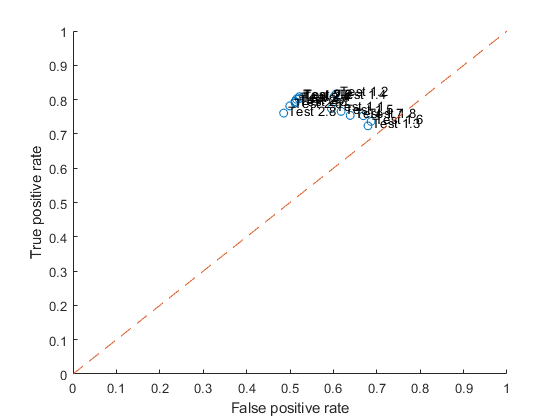

scatter(falsePositiveRates,truePositiveRates);
str = ["Test 1.1" "Test 1.2" "Test 1.3" "Test 1.4" "Test 1.5" "Test 1.6" "Test 1.7" "Test 1.8" "Test 2.1" "Test 2.2" "Test 2.3" "Test 2.4" "Test 2.5" "Test 2.6" "Test 2.7" "Test 2.8"];
str = cellstr(str);
dx = 0.01; dy = 0.01;
text(falsePositiveRates+dx,truePositiveRates+dy,str)
hold on 
plot(0:1,0:1,'--')
hold off
xlabel('False positive rate')
ylabel('True positive rate')

Bounded collision detection criterion ?

% colDet = zeros(1,numberOfSets);
% for i = 1 : numberOfSets
%     colDet(i) = bcdc(meanTraces(1,:),meanTraces(i,:));
% end
% plot(colDet)
% grid on
% line([0 110],[max(colDet(1:10)) max(colDet(1:10))],'Color','red','LineStyle','--')
% %Calculate accuracy, false positives, false negatives
% maxDet = max(colDet(1:10));
% falsePos = 0;
% falseNeg = 0;
% for i = 11 : numberOfSets
%     if (colDet(i)<=maxDet)
%         if (hammingWeight(hex2dec(inputs_b(i*50,:)))~=hw)
%             falsePos = falsePos +1;
%         end
%     end
% end
% falsePos
% falsePosRate = falsePos / (numberOfSets - 10) *100
% for i = 11 : numberOfSets
%     if (colDet(i)>=maxDet)
%         if (hammingWeight(hex2dec(inputs_b(i*50,:)))==hw)
%             falseNeg = falseNeg +1;
%         end
%     end
% end
% falseNeg
% falseNegRate = falseNeg / (numberOfSets - 10) * 100
% 
% accuracy = (numberOfSets - 10 - falsePos - falseNeg)/(numberOfSets - 10) *100

Use the filtered signal

% %Get the mean traces by sets of 50
% meanTraces2 = zeros(numberOfSets,size(traces_filt,2));
% 
% for i = 1 : numberOfSets
%     meanTraces2(i,:)=mean(traces_filt((i-1)*setSize+1:i*setSize,:),1);
% end

%Calculate euclidean distance with respect to the first average set trace
% euclidDistances2 = zeros(1,numberOfSets);
% 
% for i = 1 : numberOfSets
%     euclidDistances2(i) = norm(meanTraces2(1,:)-meanTraces2(i,:));
% end
% plot(euclidDistances2)
% grid on
% hold on
% plot(euclidDistances)
% line([0 110],[max(euclidDistances2(1:10)) max(euclidDistances2(1:10))],'Color','red','LineStyle','--')
% hold off
% grid on
% 
% %Calculate accuracy, false positives, false negatives
% maxDist = max(euclidDistances2(1:10));
% falsePos = 0;
% falseNeg = 0;
% for i = 11 : numberOfSets
%     if (euclidDistances2(i)<=maxDist)
%         if (hammingWeight(hex2dec(inputs_b(i*50,:)))~=hw)
%             falsePos = falsePos +1;
%         end
%     end
% end
% falsePos
% falsePosRate = falsePos / (numberOfSets - 10) *100
% for i = 11 : numberOfSets
%     if (euclidDistances2(i)>=maxDist)
%         if (hammingWeight(hex2dec(inputs_b(i*50,:)))==hw)
%             falseNeg = falseNeg +1;
%         end
%     end
% end
% falseNeg
% falseNegRate = falseNeg / (numberOfSets - 10) * 100
% 
% accuracy = (numberOfSets - 10 - falsePos - falseNeg)/(numberOfSets - 10) *100

Correlation ?

% corrs2 = zeros(1,numberOfSets);
% for i = 1 : numberOfSets
%     corr = corrcoef(meanTraces2(1,:),meanTraces2(i,:));
%     corrs2(i) = corr(1,2);
% end
% plot(corrs2)
% hold on 
% plot(corrs)
% line([0 110],[min(corrs2(1:10)) min(corrs2(1:10))],'Color','red','LineStyle','--')
% hold off
% grid on
% %Calculate accuracy, false positives, false negatives
% minCorr = min(corrs2(1:10));
% falsePos = 0;
% falseNeg = 0;
% for i = 11 : numberOfSets
%     if (corrs2(i)>=minCorr)
%         if (hammingWeight(hex2dec(inputs_b(i*50,:)))~=hw)
%             falsePos = falsePos +1;
%         end
%     end
% end
% falsePos
% falsePosRate = falsePos / (numberOfSets - 10) *100
% for i = 11 : numberOfSets
%     if (corrs2(i)<=minCorr)
%         if (hammingWeight(hex2dec(inputs_b(i*50,:)))==hw)
%             falseNeg = falseNeg +1;
%         end
%     end
% end
% falseNeg
% falseNegRate = falseNeg / (numberOfSets - 10) * 100
% 
% accuracy = (numberOfSets - 10 - falsePos - falseNeg)/(numberOfSets - 10) *100

Bounded collision detection criterion ?

% colDet2 = zeros(1,numberOfSets);
% for i = 1 : numberOfSets
%     colDet2(i) = bcdc(meanTraces2(1,:),meanTraces2(i,:));
% end
% plot(colDet2)
% grid on
% hold on 
% plot(colDet)
% line([0 110],[max(colDet2(1:10)) max(colDet2(1:10))],'Color','red','LineStyle','--')
% hold off
% %Calculate accuracy, false positives, false negatives
% maxDet = max(colDet2(1:10));
% falsePos = 0;
% falseNeg = 0;
% for i = 11 : numberOfSets
%     if (colDet2(i)<=maxDet)
%         if (hammingWeight(hex2dec(inputs_b(i*50,:)))~=hw)
%             falsePos = falsePos +1;
%         end
%     end
% end
% falsePos
% falsePosRate = falsePos / (numberOfSets - 10) *100
% for i = 11 : numberOfSets
%     if (colDet2(i)>=maxDet)
%         if (hammingWeight(hex2dec(inputs_b(i*50,:)))==hw)
%             falseNeg = falseNeg +1;
%         end
%     end
% end
% falseNeg
% falseNegRate = falseNeg / (numberOfSets - 10) * 100
% 
% accuracy = (numberOfSets - 10 - falsePos - falseNeg)/(numberOfSets - 10) *100